clc;clear

load('DatosExperimentales.mat')
v=[time uPRBS];
N=length(uPRBS);
Np=50; %Tamaño de la población
CR=0.8; %Probabilidad de cruce
F=0.6; %Peso diferencial
MaxIter=400;
lb=zeros(1,15); %Límite inferior
ub=[.5 .5 .5 1 1.5 2 2 2 2 2 2 2 2 0.5 0.3]; %Límite superior
%a1 a2 a3 b1 alpha c1 c2 c3 c4 d1 d2 r1 r2 s rho

dim=length(lb); %Dimension
Pop=repmat(lb,Np,1) + repmat((ub-lb),Np,1).*rand(Np,dim); %Poblacion inicial
Cost=zeros(Np,1);
%Evaluar la poblacion inicial
for p=1:Np    
    y=Pop(p,:);
    try
        sim("modelo_metaheur.slx")
    catch
        Test=inf(N,1);
    end
    if length(Test)<N
        Test=inf(N,1);
    end
    Cost(p)=sum((TexpPRBS-Test).^2)/N;
end

tic
rep=0;
[~,indBest]=min(Cost);
MejoresParametros=Pop(indBest,:);
TrayParam=MejoresParametros; %Trayectoria de los parametros
TrayCost=min(Cost); %Trayectoria del costo
disp(['Iteración ' num2str(rep) ': Mejor Costo = ' num2str(min(Cost))])

Iteración 0: Mejor Costo = 0.0011285



while rep<MaxIter || min(Cost)<10^(-5) %Condicion de parada
    trial=zeros(Np,dim);
    CostTrial=zeros(Np,1);

    for i=1:Np
        Candidates=[1:i-1 i+1:Np];
        ind=Candidates(randperm(Np-1,3));
        %Tres individuos aleatorios
        a=Pop(ind(1),:); 
        b=Pop(ind(2),:);
        c=Pop(ind(3),:);
        V=a+F*(b-c);
        R=randi(dim,1);
        %Nuevo Individuo
        for j=1:dim
            ri=rand();
            if (ri<=CR) || j==R
                trial(i,j)=V(j);
            else
                trial(i,j)=Pop(i,j);
            end
        end
    end
    for i=1:Np
        for j=1:dim %En caso que se salga de los limites
            if trial(i,j)<lb(j) || trial(i,j)>ub(j)
                trial(i,j)=lb(j)+rand()*(ub(j)-lb(j));
            end
        end
        % trial(i,:)=min(ub,trial(i,:));
        % trial(i,:)=max(lb,trial(i,:));
        y=trial(i,:);
        try
            sim("modelo_metaheur.slx")
        catch
            Test=inf(N,1);
        end
        if length(Test)<N
            Test=inf(N,1);
        end
        CostTrial(i)=sum((TexpPRBS-Test).^2)/N;
        if CostTrial(i)<Cost(i)
           Pop(i,:)=trial(i,:);
           Cost(i)=CostTrial(i);
        end
    end
    rep=rep+1;

    [~,indBest]=min(Cost);
    MejoresParametros=Pop(indBest,:);
    
    TrayParam=[TrayParam
                MejoresParametros];
    TrayCost=[TrayCost
            min(Cost)];
    disp(['Iteración ' num2str(rep) ': Mejor Costo = ' num2str(min(Cost))])
end

Iteración 1: Mejor Costo = 0.0011285
Iteración 2: Mejor Costo = 0.0011285
Iteración 3: Mejor Costo = 0.0011285
Iteración 4: Mejor Costo = 0.0011285
Iteración 5: Mejor Costo = 0.0011285
Iteración 6: Mejor Costo = 0.0011285
Iteración 7: Mejor Costo = 0.0011285
Iteración 8: Mejor Costo = 0.0011285
Iteración 9: Mejor Costo = 0.0010038
Iteración 10: Mejor Costo = 0.0010038
Iteración 11: Mejor Costo = 0.0010038
Iteración 12: Mejor Costo = 0.0010038
Iteración 13: Mejor Costo = 0.0010038
Iteración 14: Mejor Costo = 0.00065231
Iteración 15: Mejor Costo = 0.00065231
Iteración 16: Mejor Costo = 0.00065231
Iteración 17: Mejor Costo = 0.00065231
Iteración 18: Mejor Costo = 0.00065231
Iteración 19: Mejor Costo = 0.00065231
Iteración 20: Mejor Costo = 0.00065231
Iteración 21: Mejor Costo = 0.00065231
Iteración 22: Mejor Costo = 0.00065231
Iteración 23: Mejor Costo = 0.00065231
Iteración 24: Mejor Costo = 0.00065231
Iteración 25: Mejor Costo = 0.00065231
Iteración 26: Mejor Costo = 0.00065231
Iteració

toc

Elapsed time is 16640.515155 seconds.


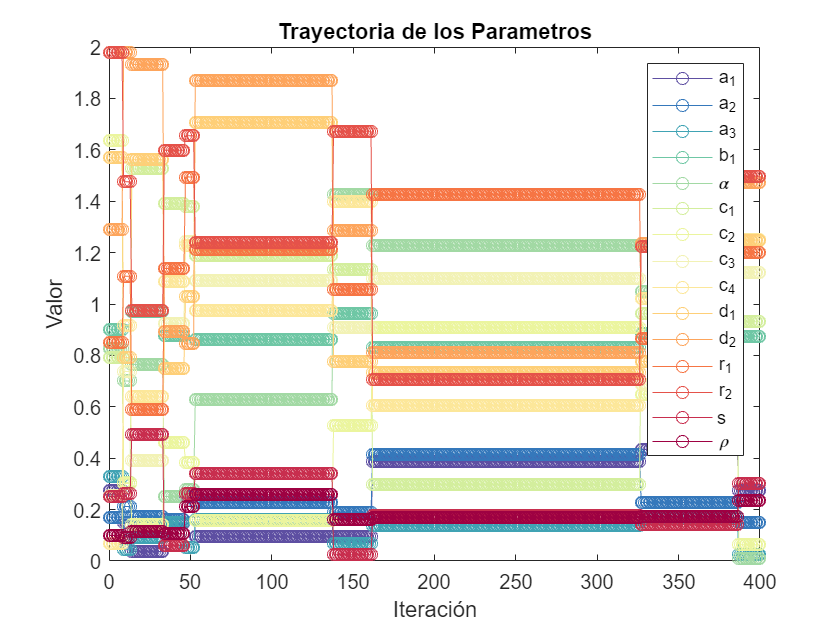

%Trayectoria de los Parametros
colors=linspecer(length(MejoresParametros));
for i=1:length(MejoresParametros)
    plot((0:rep),TrayParam(:,i),'Marker','o','Color',colors(i,:))  
    hold on
end
title("Trayectoria de los Parametros")
xlabel('Iteración')
ylabel('Valor')
xlim([0,rep])
legend(["a_1","a_2", "a_3", "b_1", "\alpha", "c_1", "c_2", "c_3", "c_4", "d_1", "d_2", "r_1", "r_2", "s" "\rho"])
hold off

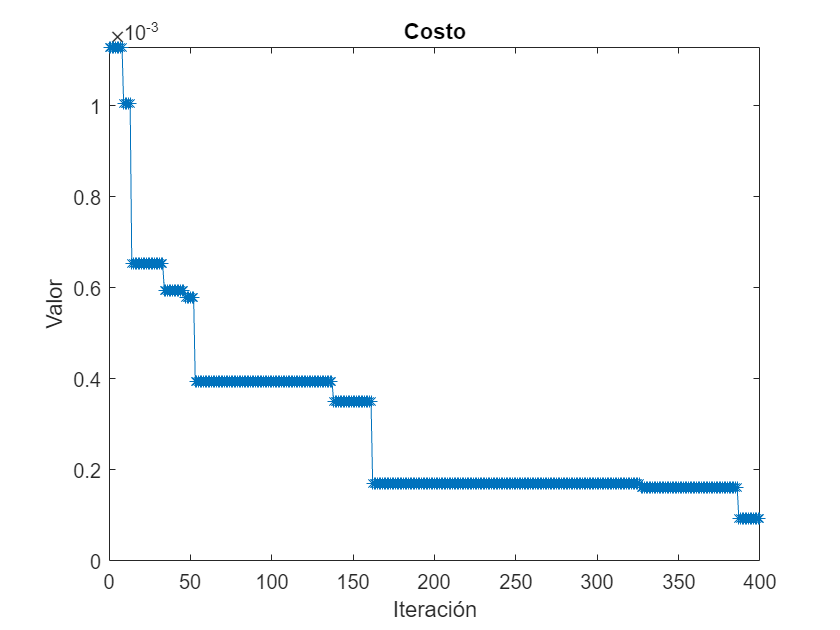



%Costo
plot(0:rep,TrayCost,'Marker','*')
xlim([0,MaxIter])
ylim([0,max(TrayCost)])
title("Costo")
xlabel('Iteración')
ylabel('Valor')

MejoresParametros=TrayParam(end,:);
tab=array2table(MejoresParametros','VariableNames',"Valor","RowNames",["a1","a2", "a3", "b1", "alpha", "c1", "c2", "c3", "c4", "d1", "d2", "r1", "r2", "s" "rho"]);
disp(tab)

              Valor  
             ________

    a1        0.27346
    a2        0.15077
    a3       0.024692
    b1        0.87461
    alpha    0.010179
    c1        0.93306
    c2       0.063631
    c3         1.1236
    c4         1.2507
    d1         1.2456
    d2         1.4743
    r1         1.2012
    r2         1.4979
    s          0.3272
    rho       0.23602



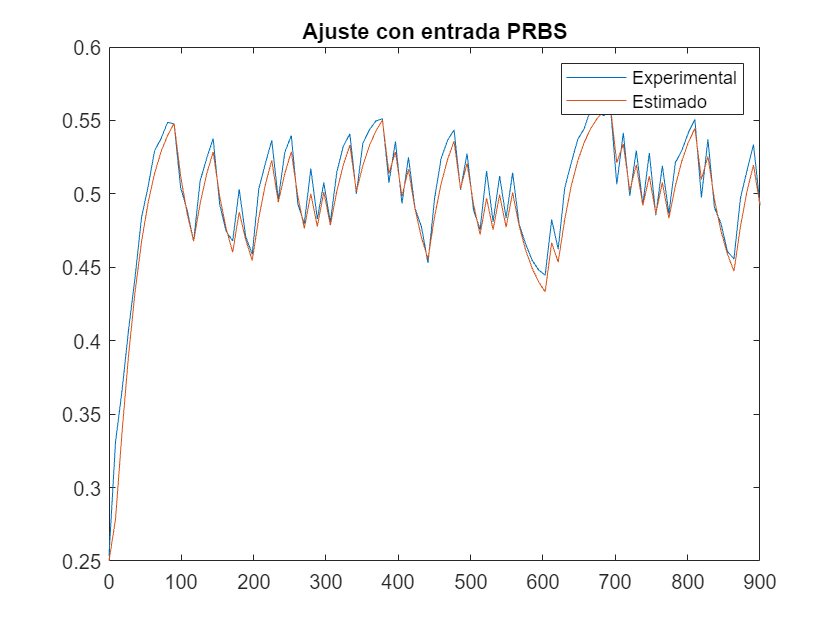

y=MejoresParametros;
sim("modelo_metaheur.slx")
plot(time,[TexpPRBS Test])
title('Ajuste con entrada PRBS')
legend(["Experimental", "Estimado"])

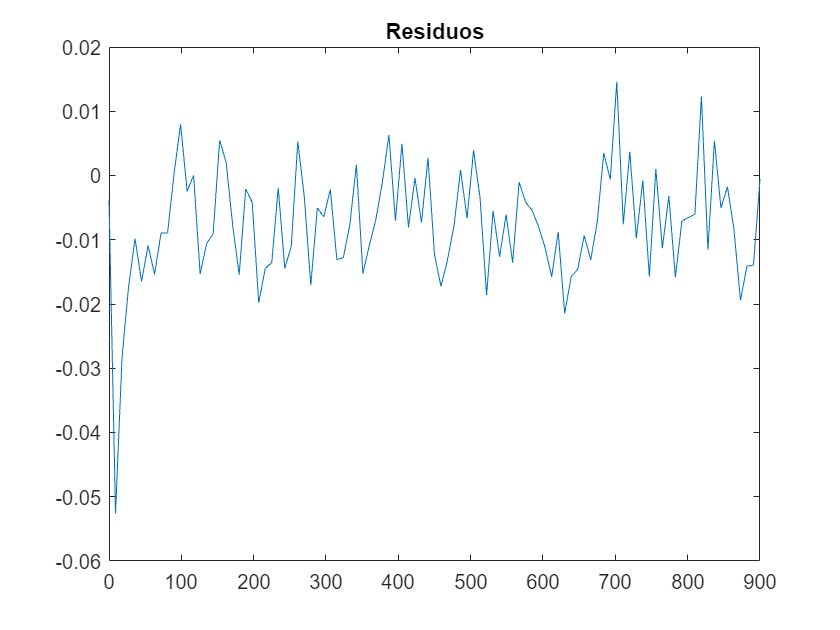

e=Test-TexpPRBS;
plot(time, e)
title('Residuos')

mean(e)

ans = -0.0076

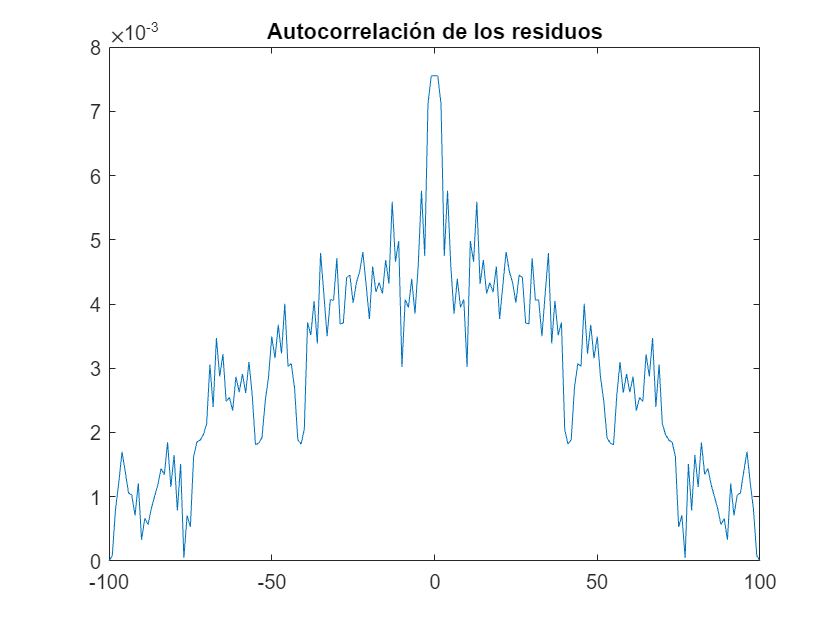

[c, lags] = xcorr(e);
lags(101)=[];
c(101)=[];
plot(lags,c)
title("Autocorrelación de los residuos")

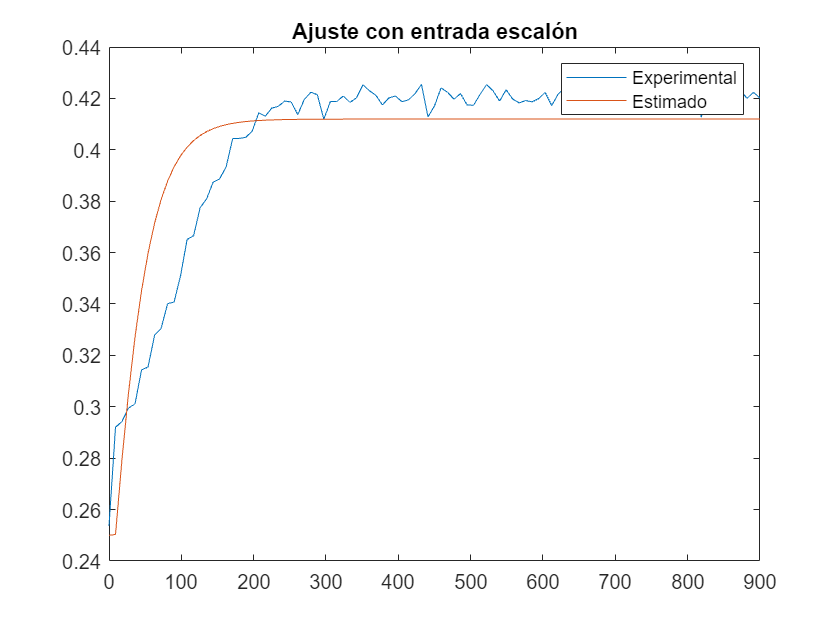

%validacion seno y escalon
v=[time uSTEP];
sim("modelo_metaheur.slx")
plot(time,[TexpSTEP Test])
title('Ajuste con entrada escalón')
legend(["Experimental", "Estimado"])

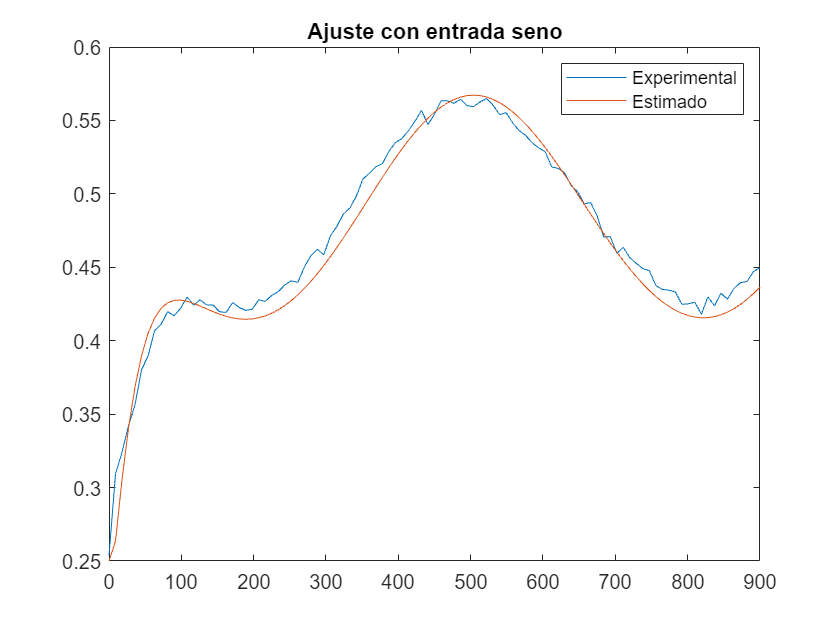


v=[time uSIN];
sim("modelo_metaheur.slx")
plot(time,[TexpSIN Test])
title('Ajuste con entrada seno')
legend(["Experimental", "Estimado"])

%Intervalos de Confianza
conf=0.05;
Npar=15;
int_conf = zeros(Npar,2);
Par0=MejoresParametros';
Par=Pop;
for i=1:Npar
    x=Par(:,i);
    N = length(x);
    xbar = mean(x);
    sigma = std(x);
    alpha = 1 - conf;
    linf = alpha/2; lsup = 1 - alpha/2;
    nu = N - 1; % Grados de libertad de la distribución t de Student
    t_stud = tinv([linf lsup], nu);
    int_conf(i,:) = xbar + t_stud*sigma/sqrt(N);
end
error_abs = round(abs(int_conf(:,2) - Par0),2,'significant');
error_rel = round(abs((error_abs./Par0))*100,2,'significant');
parNames={'a1','a2','a3','b1','alpha','c1','c2','c3','c4','d1','d2','r1','r2','rho','s'};
tab=array2table([Par0 error_abs error_rel], 'RowNames',parNames,'VariableNames',{'Estimados', 'Intervalo de confianza', 'Error relativo(%)'});
disp(tab)

             Estimados    Intervalo de confianza    Error relativo(%)
             _________    ______________________    _________________

    a1        0.27346             0.042                     15       
    a2        0.15077             0.087                     58       
    a3       0.024692              0.11                    450       
    b1        0.87461             0.006                   0.69       
    alpha    0.010179              0.69                   6800       
    c1        0.93306              0.17                     18       
    c2       0.063631              0.51                    800       
    c3         1.1236             0.059                    5.3       
    c4         1.2507              0.15     